Actividades clase 2, 29 abril

Diferentes cálculos de una sumatoria que se pueden hacer en matlab, ya sea por medio de for o utilizando vectores. Se debe tratar de evitar los for a toda costa, puesto que requieren de una gran cantidad de procesamiento. 

Usando for

%cálculo de una sumatoria usando for
m=10;
S=0;
for j=1:1:m
    S=(j*j+1)*sin(j)+S;
end
disp('El resultado de la suma es: ');

El resultado de la suma es: 


disp(S);

   35.5098



usando vectores

%calculo de la sumatoria utilizando el producto de vectores de matlab
x=1:m;
y=(x.^2+1).*sin(x);
S=sum(y);
disp(S);

   35.5098



producto punto con el producto de vectores

%cálculo del producto punto usando el producto de vectores matlab
x=[1,2,3,4];
y=[4,3,2,1];
p=x.*y;
ab=sum(p);
disp(ab);

    20



cálculo directo del producto punto

%matlab directamente calcula el producto punto
a=[1,2,3,4,5];
b=[5,4,3,2,1];
p=dot(a,b);
disp(p);

    35



grafica usando for

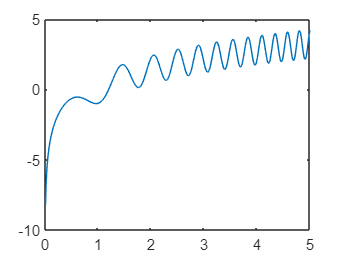

%graficar una función utilizando for 
x=0:0.01:5;
for j=1:length(x)
    f(j)=exp(0.002*x(j)*x(j))*cos(3*x(j)*x(j))+log(x(j)*x(j));
end
plot(x,f);

grafica usando vectores. hay que tener muy en cuenta cuando se utiliza * y cuando es necesairo .*.

%graficar una función utilizando vectores
x=0:0.01:5;
f=exp(0.002*x.^2).*cos(3*x.^2)+log(x.^2);
plot(x,f);

Ahora cómo editar una matriz utilizando una redefinición.

A=randi([-100,100],9,9);
A(2:4,5:8)=zeros(3,4);
disp(A);

    29    17   -55   -78   -41    46    -2    60    -1
   -24   -59   -13   -49     0     0     0     0    56
    63   -40   -38   -18     0     0     0     0    43
     7    -6    85    19     0     0     0     0    81
   -30   -54   -14   -48   -83    -8   -27    36    79
    88    69   -63    21   -48    93    98   -73   -33
    76   -61    81    42    61     9   -93    44    40
    10   -55    96   -56   -95     4    77   -79   -61
    25   -66   -12   -77    86   -54    83    31   -94



Y como editar una matriz usando for.

A=randi([-100,100],10,10);
n=8;
m=9;
s=1;
t=9;
for j=n:m
    for i=s:t
        A(j,i)=0;
    end
end
disp(A);

    49   -52    37     4   -22   -14    84    40    12   -25
     0    78   -92    95    67   -97   -90    33    77   -62
    -4   -95   -86    30    61    97    48     8    34   -14
    81    -2     4    60   -88   -67   -46    40   -62    -4
    22   -67   -81    -9   -20   -79   -16    33   -26   -76
    24    96    64   -14     5   -26    10   -65    -8    18
    72    43    64    65   -17   -61    89   -75    97   -55
     0     0     0     0     0     0     0     0     0   -23
     0     0     0     0     0     0     0     0     0    17
   -64   -89    32   -66   -42    91   -40   -94    29   -50

